# Edgeworth-Bowley

**Overview**

The `EdgeworthBowley` chart provides a means to represent various distributions of resources. It is a conceptual device for analysing possible trading relationships between two individuals or countries, using indifference curves. It is constructed by taking the indifference map of one individual (B) for two goods (X and Y) and inverting it to face the indifference map of a second individual (A) for the same two goods.

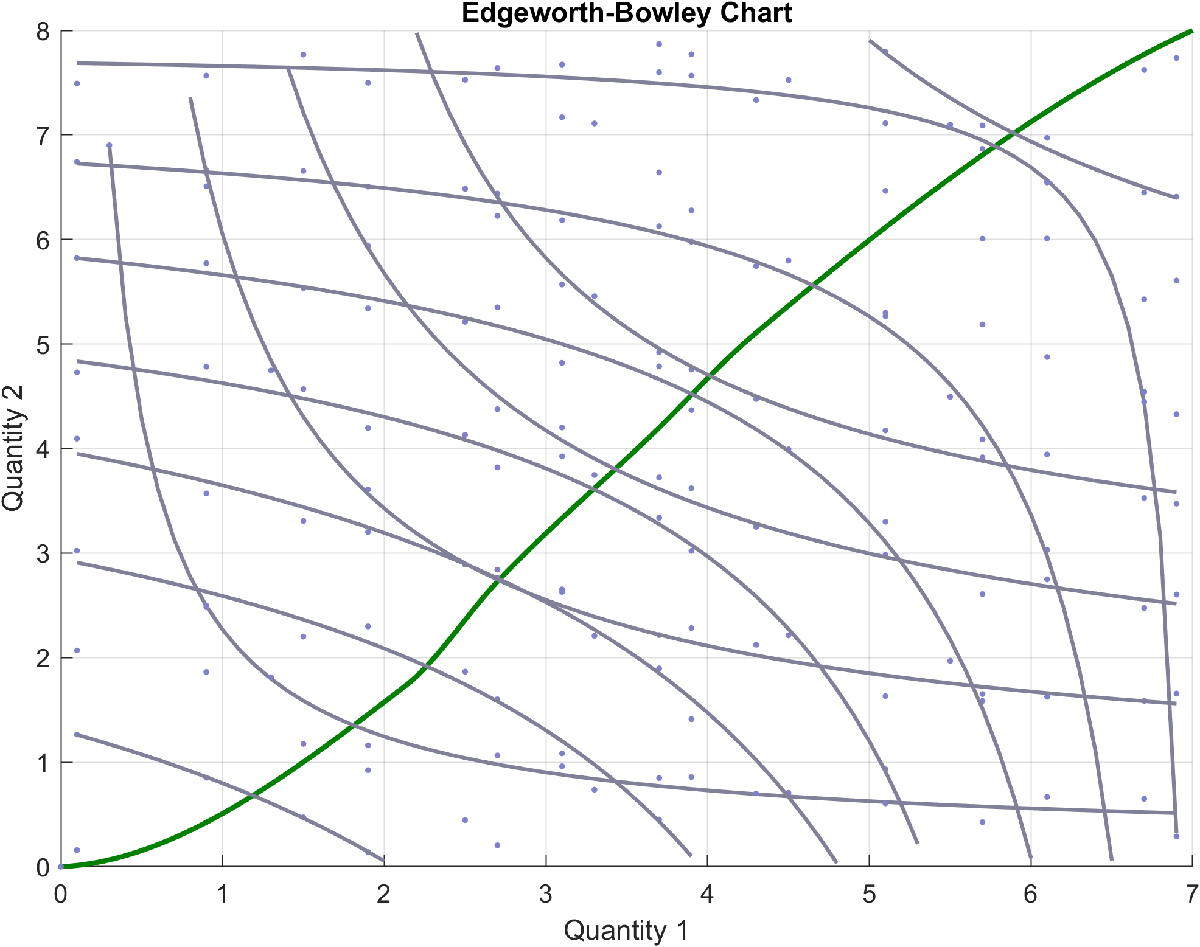

**Resources**

[Open](matlab: edit(fullfile(catalogRoot(), "+example", "EdgeworthBowley.mlx"))) this Live Script to run and interact with the examples shown below.

[View](matlab: edit(fullfile(catalogRoot(), "+chart", "EdgeworthBowley.m"))) the source code for the `EdgeworthBowley` chart.

Documentation for:

- [fitnlm](matlab: doc( "fitnlm" )): fit a nonlinear regression model

## Load some sample chart data.

The chart input data should comprise two matrices, one for individual A and one for individual B. The first column of each matrix should be an equally-spaced, increasing vector with a maximum value of `Quantity1`, the first quantity under consideration.

The subsequent matrix columns are the indifference curves, storing the corresponding quantity of the second resource for the given quantity of the first quantity in the first column. If data is unavailable for the specific point, then it should be represented using a [NaN](matlab: doc("NaN")) (not a number). 

It is recommended to create the chart data by starting with matrices of `NaN`s, and then assign the available indifference curve values.

For example, a sample matrix $A$ for the Edgeworth-Bowley chart could be as follows.


$$A = \left[\begin{array}{cccccc}0.1 & 9.5 & \vdots & \dots & \vdots & \text{NaN}\\0.2 & 4.5 & \vdots & \dots & \vdots & \text{NaN}\\0.3 & 3 & \vdots & \dots & \vdots & 9.7\\\vdots & \vdots & \vdots & \dots & \vdots & \vdots\\0.9 & 2.55 & \vdots & \dots & \vdots & 4.55\\1.0 & 2.5 & \vdots & \dots & \vdots & 4.5\end{array}\right]$$


load( fullfile( catalogRoot(), "data", "IndifferenceCurves.mat" ), "A", "B" )
disp("Chart A-data:")

Chart A-data:


disp(A)

    0.1000       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    0.2000       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    0.3000    6.9011       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    0.4000       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    0.5000       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    0.6000       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    0.7000       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    0.8000       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    0.9000    2.4973    6.6603       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
 

disp("Chart B-data:")

Chart B-data:


disp(B)

    0.1000       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    0.2000       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    0.3000    3.5543       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    0.4000       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    0.5000       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    0.6000       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    0.7000       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    0.8000       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    0.9000    1.4537    4.9690    9.0693       NaN       NaN       NaN       NaN       NaN       NaN       NaN
 

## Create a figure for the chart.

f = exampleFigure( "Name", "Edgeworth-Bowley Example" );

## Create the chart, specifying the parent and input data.

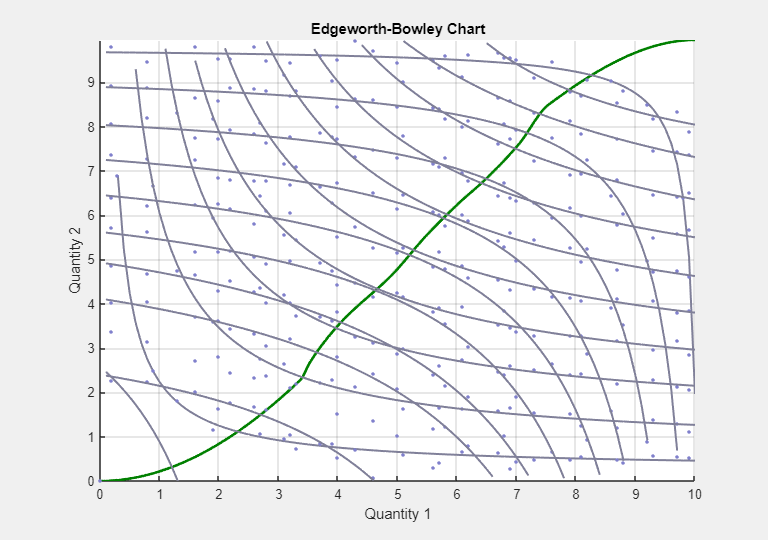

EB = chart.EdgeworthBowley( "Parent", f, ...   
    "AData", A, ...
    "BData", B );

## Redefine the maximum resource values.

First, increase the quantity of resource 1.

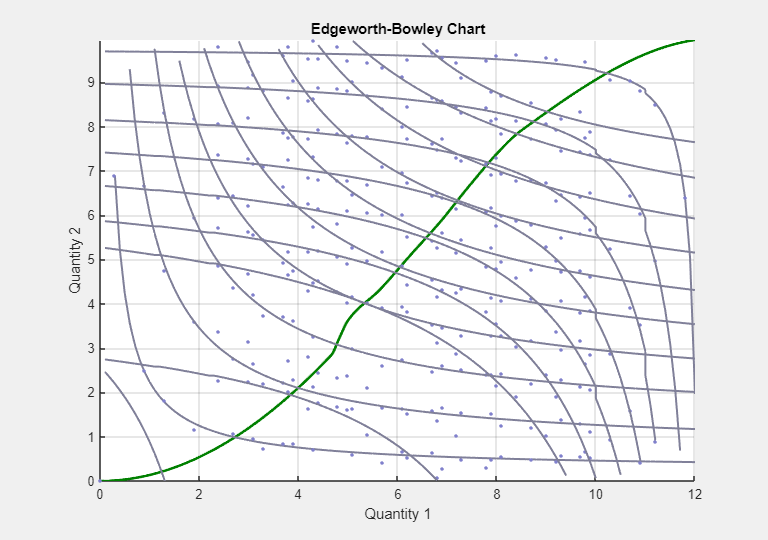

EB.Quantity1 = 12;

## Decrease the quantity of resource 1.

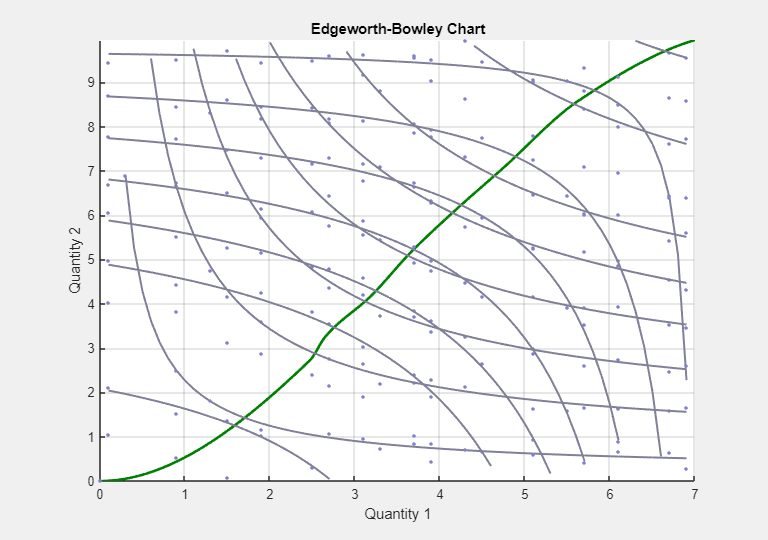

EB.Quantity1 = 7;

## Increase the quantity of resource 2.

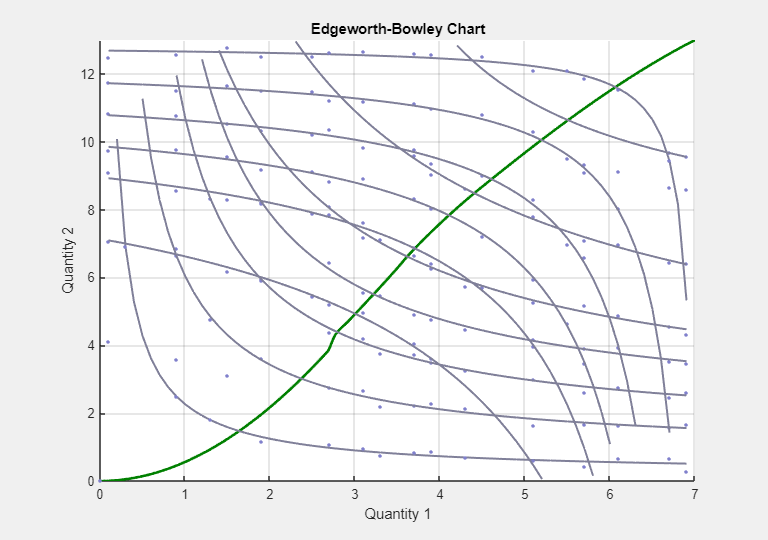

EB.Quantity2 = 13;

## Decrease the quantity of resource 2.

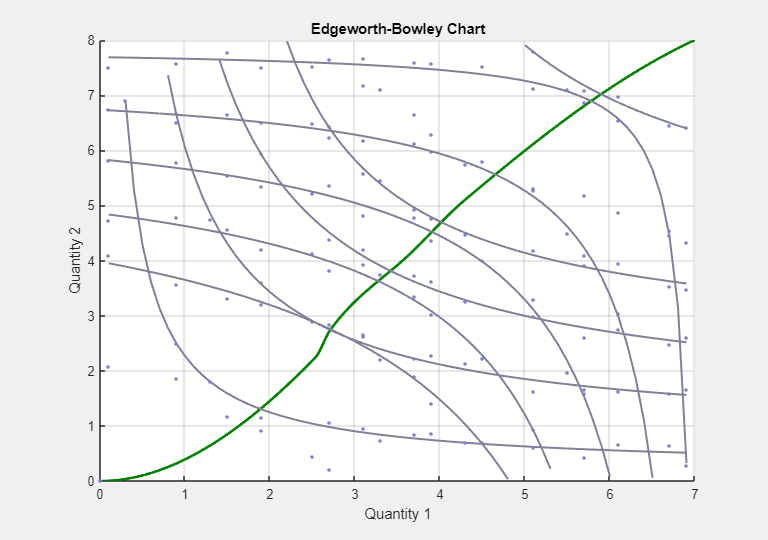

EB.Quantity2 = 8;

*Copyright 2018-2021 The MathWorks, Inc.*